clear; clc; close all;


MARS ISRU PROPELLANT PLANT SIZING TOOL

Matei Lungu 11327340 - University of Manchester

Kleinhenz & Paz (2017) baseline used for subsystem mass scaling

## USER INPUTS

% Choose a mode for this tool to run 
mode = "Mass -> Power"      ;


target_propellant_kg = 30000;
available_power_kW   =   10;

% Shared inputs
mission_days  = 510; % Mission Duration (Days)
OF_ratio      = 3.5; % Oxidiser to Fuel Ratio
eta_thermal   = 0.6; % Heat Exchanger Thermal Efficiency
eta_SOE       = 0.85; % Electrolysis efficiency

% Storage tanks needed?
include_storage = true; % yes = add 5% propellant mass as storage tanks
                                        % no = MAV co-located, no storage needed


## CONSTANTS


M_CH4 = 16.043;
M_O2  = 31.998;
M_CO2 = 44.010;
M_H2O = 18.015;

dH_sabatier = 165;
dH_electro  = 286;

irradiance   = 590;
eta_cell     = 0.335;
eta_pack     = 0.90;
sun_angle    = 15;
dust_degrade = 0.02; % fixed per mission not per year
T_eclipse    = 12.6;
T_sun        = 12.0;
DoD          = 0.50;
V_bus        = 120;
rho_battery  = 285;
rho_solar    = 1.8;

rho_kilopower = 154.4;
rho_RTG       = 6.0;

base_propellant = 30000;
base_days       = 510;
base_excavation = 110;
base_regolith   = 705;
base_atmos      = 415;
base_propProd   = 210;
base_liq        = 145;


## STOICHIOMETRY


if mode == "Mass -> Power"
    mass_CH4 = target_propellant_kg / (1 + OF_ratio);
    mass_O2  = target_propellant_kg - mass_CH4;
    n_CH4    = (mass_CH4 * 1000) / M_CH4;

elseif mode == "Power -> Mass"
    % Auxiliaries take a fixed fraction of total power
    % Based on baseline: P_chem/P_total ratio from baseline
    % At baseline: P_chem = 11.76, P_total = 32.76, so chem fraction = 0.359
    chem_fraction = 11.76 / 32.76;
    P_chem_available = available_power_kW * chem_fraction;
    
    E_batch_J  = (4 * dH_electro * 1000) / eta_SOE;
    E_regen_J  = dH_sabatier * 1000 * eta_thermal;
    E_net_J    = E_batch_J - E_regen_J;

    target_batch_g       = M_CH4 + M_CH4 * OF_ratio;
    specific_energy_J_kg = E_net_J / (target_batch_g / 1000);

    prod_rate_kg_s       = (P_chem_available * 1000) / specific_energy_J_kg;
    prod_rate_kg_day     = prod_rate_kg_s * 3600 * 24;
    target_propellant_kg = prod_rate_kg_day * mission_days;

    mass_CH4 = target_propellant_kg / (1 + OF_ratio);
    mass_O2  = target_propellant_kg - mass_CH4;
    n_CH4    = (mass_CH4 * 1000) / M_CH4;
end

n_H2O_split     = 4 * n_CH4;
n_H2O_byproduct = 2 * n_CH4;
n_H2O_mined     = n_H2O_split - n_H2O_byproduct;
n_O2_produced   = n_H2O_split / 2;

mass_CO2_kg    = (n_CH4 * M_CO2) / 1000;
mass_water_kg  = (n_H2O_mined * M_H2O) / 1000;
mass_O2_prod   = (n_O2_produced * M_O2) / 1000;
mass_O2_excess = mass_O2_prod - mass_O2;


## ENERGY & THERMAL


E_electro_kWh  = (n_H2O_split * dH_electro) / 3600;
E_gross_kWh    = E_electro_kWh / eta_SOE;
E_sabatier_kWh = (n_CH4 * dH_sabatier) / 3600;
E_regen_kWh    = E_sabatier_kWh * eta_thermal;
E_net_kWh      = E_gross_kWh - E_regen_kWh;

hours     = mission_days * 24;
P_chem_kW = E_net_kWh / hours;

scale_throughput = (target_propellant_kg / mission_days) / (base_propellant / base_days);
P_regolith = 11 * scale_throughput;
P_atmos    = 3  * scale_throughput;
P_liq      = 7  * scale_throughput;

if mode == "Mass -> Power"
    P_total = P_chem_kW + P_regolith + P_atmos + P_liq;
else
    P_total = available_power_kW;
end


## SUBSYSTEM MASS SCALING


mass_excavation = base_excavation * scale_throughput;
mass_regolith   = base_regolith   * scale_throughput;
mass_atmos      = base_atmos      * scale_throughput;
mass_propProd   = base_propProd   * scale_throughput;
mass_liq        = base_liq        * scale_throughput;
mass_plant_dry  = mass_excavation + mass_regolith + mass_atmos + mass_propProd + mass_liq;

if include_storage
    mass_storage = 0.05 * target_propellant_kg;
else
    mass_storage = 0;
end


## POWER SYSTEM SIZING


D        = dust_degrade * (mission_days / 365);
C_batt   = (P_total * 1000 * T_eclipse) / (DoD * V_bus);
M_battery = (C_batt * V_bus) / rho_battery;
R_ch     = (DoD * C_batt) / T_sun;
P_charge = (R_ch * V_bus) / 1000;
P_EOL    = P_total + P_charge;
A_array  = (P_EOL * 1000) / (irradiance * eta_cell * eta_pack * (1 - D) * cosd(sun_angle));
M_array  = A_array * rho_solar;
M_solar  = M_array + M_battery;

M_kilopower = P_total * rho_kilopower;
M_RTG       = (P_total * 1000) / rho_RTG;

M_total_solar = mass_plant_dry + mass_storage + M_solar;
M_total_kilo  = mass_plant_dry + mass_storage + M_kilopower;
M_total_RTG   = mass_plant_dry + mass_storage + M_RTG;


## OUTPUT


fprintf('\n=================================================\n');

if mode == "Mass -> Power"
    fprintf(' MARS ISRU SIZING TOOL - MODE 1 (Mass to Power)\n');
else
    fprintf(' MARS ISRU SIZING TOOL - MODE 2 (Power to Mass)\n');
end

 MARS ISRU SIZING TOOL - MODE 1 (Mass to Power)


fprintf('=================================================\n');

fprintf('MISSION:\n');

MISSION:


fprintf('  Propellant Target:    %.0f kg\n', target_propellant_kg);

  Propellant Target:    1000 kg


fprintf('  Mission Duration:     %d days\n', mission_days);

  Mission Duration:     800 days


fprintf('  Production Rate:      %.2f kg/day\n', target_propellant_kg/mission_days);

  Production Rate:      1.25 kg/day


fprintf('  Storage Tanks:        %s\n', mat2str(include_storage));

  Storage Tanks:        true


fprintf('\nMASS BALANCE:\n');


MASS BALANCE:


fprintf('  CO2 Required:         %.0f kg\n', mass_CO2_kg);

  CO2 Required:         610 kg


fprintf('  Water Ice Mined:      %.0f kg\n', mass_water_kg);

  Water Ice Mined:      499 kg


fprintf('  Methane Produced:     %.0f kg\n', mass_CH4);

  Methane Produced:     222 kg


fprintf('  Oxygen Produced:      %.0f kg\n', mass_O2);

  Oxygen Produced:      778 kg


fprintf('  Excess Oxygen:        %.0f kg\n', mass_O2_excess);

  Excess Oxygen:        109 kg


fprintf('\nENERGY:\n');


ENERGY:


fprintf('  Gross Electrical:     %.0f kWh\n', E_gross_kWh);

  Gross Electrical:     5179 kWh


fprintf('  Thermal Recovery:     %.0f kWh\n', E_regen_kWh);

  Thermal Recovery:     381 kWh


fprintf('  Net Demand:           %.0f kWh\n', E_net_kWh);

  Net Demand:           4798 kWh


fprintf('  Total Power Required: %.2f kW\n', P_total);

  Total Power Required: 0.70 kW


fprintf('\nSUBSYSTEM MASSES:\n');


SUBSYSTEM MASSES:


fprintf('  Excavation:           %.1f kg\n', mass_excavation);

  Excavation:           2.3 kg


fprintf('  Regolith Processing:  %.1f kg\n', mass_regolith);

  Regolith Processing:  15.0 kg


fprintf('  Atmospheric Capture:  %.1f kg\n', mass_atmos);

  Atmospheric Capture:  8.8 kg


fprintf('  Propellant Prod:      %.1f kg\n', mass_propProd);

  Propellant Prod:      4.5 kg


fprintf('  Liquefaction:         %.1f kg\n', mass_liq);

  Liquefaction:         3.1 kg


fprintf('  Storage Tanks:        %.1f kg\n', mass_storage);

  Storage Tanks:        50.0 kg


fprintf('\nPOWER SYSTEM COMPARISON:\n');


POWER SYSTEM COMPARISON:


fprintf('  Solar + Battery:      %.0f kg  (Array: %.1f m2)\n', M_solar, A_array);

  Solar + Battery:      77 kg  (Array: 8.7 m2)


fprintf('  Kilopower Fission:    %.0f kg\n', M_kilopower);

  Kilopower Fission:    107 kg


fprintf('  RTG:                  %.0f kg\n', M_RTG);

  RTG:                  116 kg


fprintf('\nTOTAL LANDED MASS:\n');


TOTAL LANDED MASS:


fprintf('  Solar + Battery:      %.0f kg\n', M_total_solar);

  Solar + Battery:      161 kg


fprintf('  Kilopower Fission:    %.0f kg\n', M_total_kilo);

  Kilopower Fission:    191 kg


fprintf('  RTG:                  %.0f kg\n', M_total_RTG);

  RTG:                  200 kg


fprintf('=================================================\n');

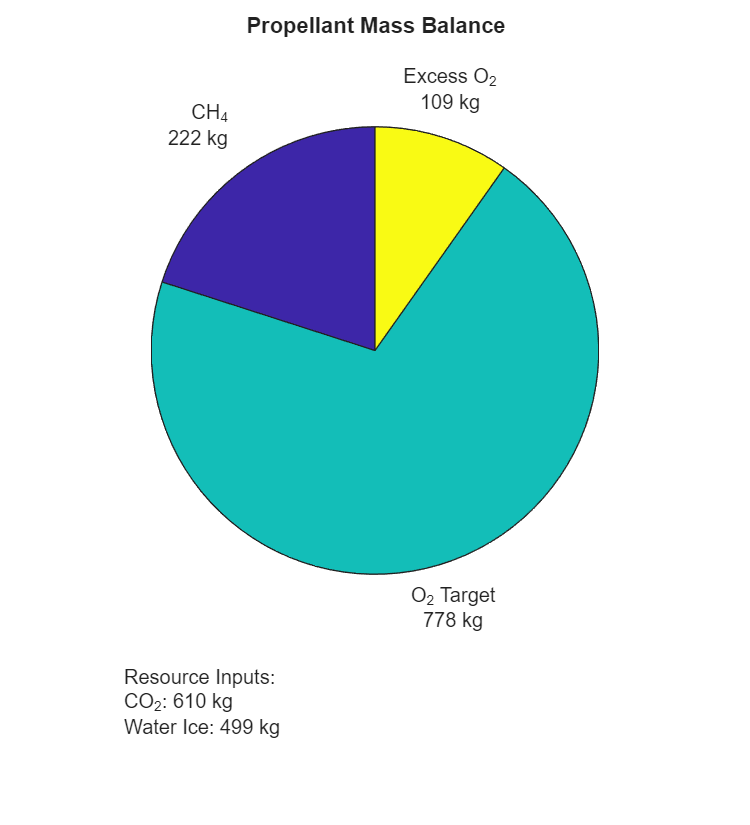


%% FIGURES
colors = [0.45,0.35,0.25;
          0.75,0.56,0.20;
          0.20,0.45,0.55;
          0.40,0.50,0.40;
          0.03,0.10,0.30;
          0.37,0.36,0.35;
          0.30,0.36,0.10];

subsys_names = {'Excavation','Regolith Processing','Atmospheric Capture', ...
                'Propellant Production','Liquefaction','Storage Tanks','Power System'};

% Figure 1: Mass balance pie
f1 = figure('Color','w','Position',[100 100 500 550]);
ax_pie = axes('Position',[0.1 0.25 0.8 0.65]);
pie(ax_pie, [mass_CH4, mass_O2, mass_O2_excess], ...
    {sprintf('CH_4\n%.0f kg', mass_CH4), ...
     sprintf('O_2 Target\n%.0f kg', mass_O2), ...
     sprintf('Excess O_2\n%.0f kg', mass_O2_excess)});
title(ax_pie, 'Propellant Mass Balance', 'Units', 'normalized', 'Position', [0.5 1.08 0]);

info_text = {sprintf('Resource Inputs:'), ...
             sprintf('CO_2: %.0f kg', mass_CO2_kg), ...
             sprintf('Water Ice: %.0f kg', mass_water_kg)};
annotation(f1, 'textbox', [0.15 0.02 0.7 0.18], 'String', info_text, ...
    'EdgeColor','none','FontSize',10,'FontName','Arial','Interpreter','tex');

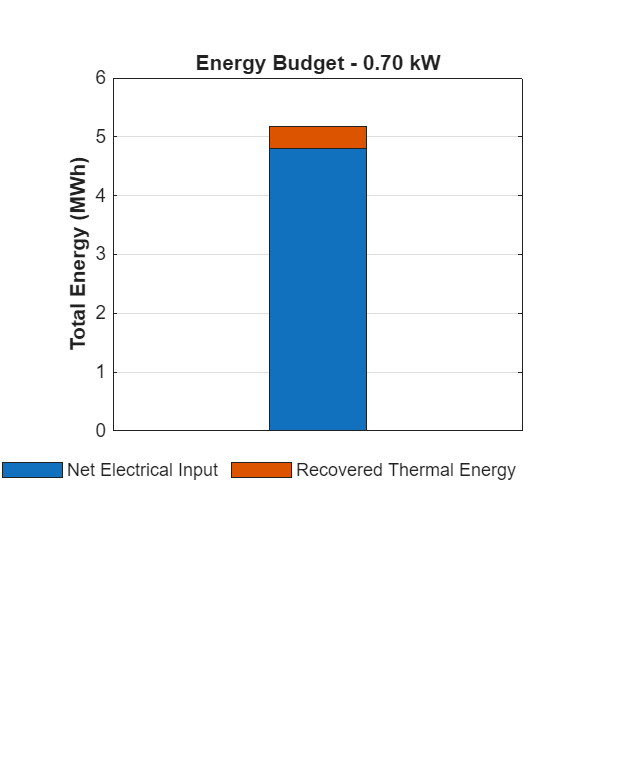


% Figure 2: Energy budget
f2 = figure('Color','w','Position',[620 100 420 520]);
ax_bar = axes('Position',[0.18 0.38 0.65 0.52]);
bar(ax_bar, 1, [E_net_kWh, E_regen_kWh]./1000, 'stacked', 'BarWidth', 0.5);
ylabel(ax_bar, 'Total Energy (MWh)', 'FontWeight', 'bold');
set(ax_bar, 'XTick', []);
title(ax_bar, sprintf('Energy Budget - %.2f kW', P_total), 'FontWeight', 'bold');
grid(ax_bar, 'on');
lgd2 = legend(ax_bar, 'Net Electrical Input','Recovered Thermal Energy', ...
    'Location', 'southoutside', 'Orientation', 'horizontal');
set(lgd2, 'Box', 'off', 'FontSize', 9);

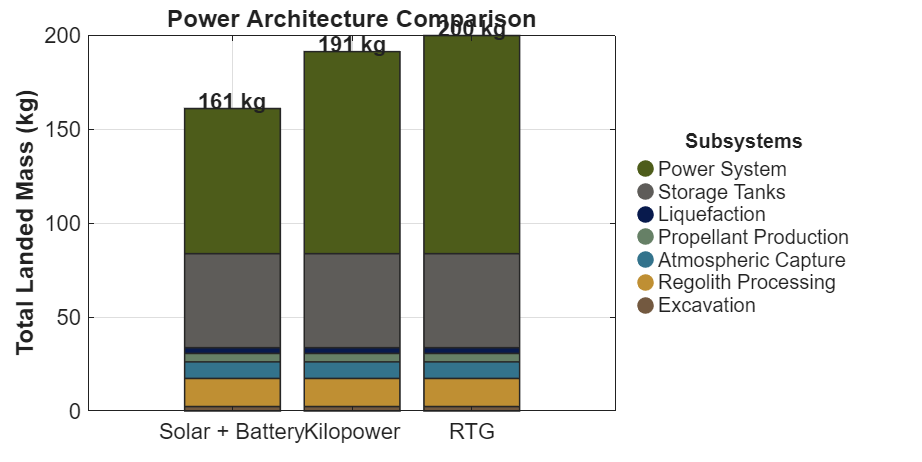


% Figure 3: Power architecture comparison
f3 = figure('Color','w','Position',[100 620 1000 500]);

plot_data = [mass_excavation, mass_regolith, mass_atmos, mass_propProd, mass_liq, mass_storage, M_solar;
             mass_excavation, mass_regolith, mass_atmos, mass_propProd, mass_liq, mass_storage, M_kilopower;
             mass_excavation, mass_regolith, mass_atmos, mass_propProd, mass_liq, mass_storage, M_RTG];

b = bar(plot_data, 'stacked', 'EdgeColor', [0.15 0.15 0.15], 'LineWidth', 0.8);
for k = 1:7
    b(k).FaceColor = colors(k,:);
end

set(gca, 'XTickLabel', {'Solar + Battery','Kilopower','RTG'}, 'FontSize', 11);
ylabel('Total Landed Mass (kg)', 'FontWeight', 'bold');
title('Power Architecture Comparison', 'FontWeight', 'bold');

totals = [M_total_solar, M_total_kilo, M_total_RTG];
for i = 1:3
    text(i, totals(i) + max(totals)*0.02, [num2str(round(totals(i))) ' kg'], ...
        'HorizontalAlignment','center','FontWeight','bold','FontSize',11);
end

hold on;
h = zeros(1,7);
for k = 1:7
    h(k) = plot(nan, nan, 'o', 'MarkerSize', 9, ...
        'MarkerFaceColor', colors(k,:), 'MarkerEdgeColor', 'none');
end
lgd3 = legend(flip(h), flip(subsys_names), 'Location', 'eastoutside');
title(lgd3, 'Subsystems');
set(lgd3, 'Box', 'off', 'FontSize', 10);
hold off;
grid on;